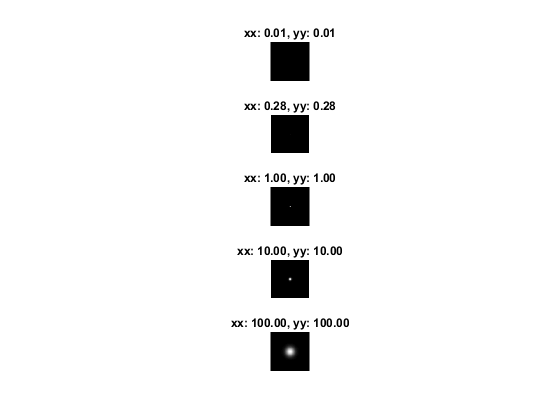

ts = [0.1, 0.3, 1.0, 10.0, 100.0];
figure()
for i = 1:length(ts)
    subplot(length(ts),1,i)
    psf = gaussfft(deltafcn(128,128), ts(i));
    filtVar = variance(psf);
    showgrey(psf)
    title(sprintf('xx: %0.2f, yy: %0.2f',filtVar(1,1), filtVar(2,2)))
end

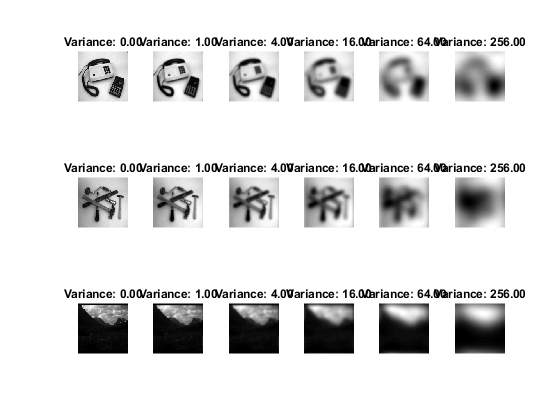

%16 ------
figure()
pics = {phonecalc128, few128, nallo128};
ts = [0.000001, 1.0, 4.0, 16.0, 64.0, 256.0];
counter = 1;
for p = 1:length(pics)
    for t = 1:length(ts)
        subplot(length(pics),length(ts),counter);
        psf = gaussfft(pics{p}, ts(t));
        showgrey(psf);
        title(sprintf('Variance: %0.2f', ts(t)));
        counter = counter + 1;
    end
end